# **Simulating the photoelectron intensity contributions of an N-layered sample**

## Author: PCC

This example shows how to use PESTools to simulate the photoelectron intensity contributions of an N-layered sample as a function of photon energy. This can be used to model experimental data obtained at ADRESS; XPS data as a function of photon energy. The function used in this example is the 'nlayer_pes_model()' function, which is quite considerable in it's scope. The function allows you to define the material type of each layer, the thickness, the core-level being probed and then determines the emitted photoelectron intensity of each layer using the Beer-Lambert law. All the material, photoionisation and core-level parameters are stored within multiple databases within the Github directory, put together by PCC.

We use the following databases here to make the initial setup of the N-layered sample user friendly:

- **Material Properties Database (MPD):** Atomic symbols, Z numbers, atomic / compound weights, electronegativity, electron affinity, ionisation energies, temperatures, crystal structures, unit cell parameters, band-gaps, work functions, electronic and magnetic properties.

material_props = get_mpd_props('U')

- **Photoionisation Cross-Section and Asymmetry Database (PIXSAD):**  This database contains all the photoionisation cross-sections and asymmetry parameters for elements 1 - 103, for orbitals that are probed with soft x-ray radiation (20 - 1500 eV). 

[hv, xsect, asymmetry] = get_pixsad_props('U', [], 950:1500)

- **Photoionisation Energy and Fluorescence Database (PIEFD):**  This database contains all the binding energies, emission / fluorescence lines, emission / fluorescence relative intensities and fluorescence yield.

piefd_props = get_piefd_props('U')

Once you define the N-layered sample, the photoelectron contributions of each layer is determined as followed:

**(1) The N-layered sample is first plotted and labelled to ensure it is defined correctly.**

**(2) Determination of the IMFP at all kinetic energies for each layer material:**

- Extract the **binding energy**, $E_B$, for each layer material core-level that is probed from the **PIEFD**.

- Extract the **work function**, $\Phi$, for each layer material from the **MPD**.

- Determine the **kinetic energy**, $E_k$, of photoelectrons for each layer material; $E_k =h\nu \;-E_B -\Phi \;$.

- Determine the **IMFP,** $\lambda_i \;$, at **all** kinetic energies for **each** layer material; the relativistic TPP-2M formalism is used to determine the IMFP.

**(3) Determine the maximum intensity **$I_0$** for each layer material: **$I_i =N_i \;F_i$.

- Determine the** total number of atoms per unit volume**, $N_i \;$, for each layer; $N_i =N_A \rho /M\;$. The **density**, $\rho$, and **atomic weight**, $M$, for each layer material is found in the **MPD**. $N_A$is the Avogadro constant.

- Extracting the **photoionisation cross section**, $\sigma_i$, for each layer, which depends on the photon energy and core-level being probed. These values are found in the **PIXSAD**.

- Extract the **asymmetry factor** ${\beta \;}_i$, for each layer, which strongly depends on the angular momentum number of the core-level being probed. These values are found in the **PIXSAD**.

- Determine the **adjusted asymmetry factor** ${\beta \;}_i^*$, which accounts for randomised elastic scattering in a solid material; ${\beta \;}_i^* =\beta \;\left(a-\textrm{bZ}+{\textrm{cZ}}^2 \right)$, where $a=0\ldotp 781,\;b=0\ldotp 00514,c=0\ldotp 000031,Z=\textrm{average}\;Z\;\textrm{number}\;\textrm{of}\;\textrm{all}\;\textrm{layers}\ldotp$

- Determine the **angular correction** **factor; **$L\left({\beta \;}_i^* ,\gamma {\;}_i \right)=1+0\ldotp 5{\beta \;}_i^* \left(1\ldotp 5\sin^2 \gamma -1\right)$, where $\gamma$is the angle between the incident x-rays and the analyser.

- Determine the **relative sensitivity factor, **$F_i$, which is: $F_i =\sigma_i \;L\left({\beta \;}_i^* ,\gamma {\;}_i \right)\;\lambda_i$.

- Finally, determine$\;I_{0,i} =N_i \;F_i$, which gives the **maximum intensity of each photoelectron component without any mitigation through the N-layered sample.**

**(4) Use the Beer-Lambert law to model the attenuation of the photoelectron intensity.**

- This model states that the photoelectron intensity decreases exponentially due to inelastic scattering, with a decay constant equal to the $\lambda_i$. 

- Thus, for a bulk, single-layer system, the Beer-Lambert law states: $I\left(z\right)=I_0 \;\exp \left(-z/\lambda \cos \theta \right)$, which gives the **photoelectron intensity**,$I$, that emerges from a **depth**, $z$, within the sample. Propagating this equation to each layer in the sample defined by the user, allows the total integral intensity of each photoelectron component for each layer in the sample stack to be determined. This is then normalised in terms of a 'relative contribution', whereby each layer is divided by the total sum of all intensities at each photon energy.

- For a 2 model system, the equations are:  $I_{\textrm{OL}} =I_{0,\textrm{OL}} \;\left(1-\exp \left(-d_{\textrm{OL}} /\lambda_{\textrm{OL}} \cos \theta \right)\right)\;\;\;\;\;\;\textrm{and}\;\;\;\;\;\;\;\;\;I_{\textrm{BULK}} =I_{0,\textrm{BULK}} \;\exp \left(-d_1 /\lambda_1 \cos \theta \right)\;$

We will now go through an example to demonstrate how to use this to solve your own problems.

# **Example models**

close all; clear all;
help nlayer_pes_model;

  pes_model = nlayer_pes_model(lyr_mat, lyr_cls, lyr_thick, hv, theta, gamma, plot_result)
    Function that determines the total photoelectron intensity originating
    from N independent layers in a sample that consists of several
    different materials of a user-defined thickness. The core-level being
    probed is also defined, as well as the experimental geometry. 
    --------------------------------------------------------------------
    The model does the following:
 
        (1)  Using the input photon energies, the electron kinetic energies
        are determined so that the attenuation length / inelastic-mean free
        path (IMFP) of electrons in each layer can be determined. 
        Using:
            Ek = Ehv - Ebe - WF ,
        Ek is the electron kinetic energy; Ehv is the input photon energy;
        Ebe is the binding energy of the electron, which is determined by
        in the Photoionisation Energy and Fluorescence Database (PIEFD)
        who

## (1) A 2-layer model (typical for oxides grown on a substrate)

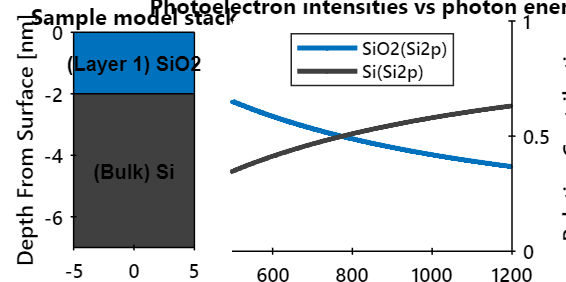

pes_hv          = linspace(500, 1200, 1e3);     % Defining the incident photon energy
lyr_mat         = {'SiO2', 'Si'};               % Defining the material of each layer, from left to right (top-to-bottom on the schematic).
lyr_cls         = {'Si2p', 'Si2p'};         % Defining the core-level being probed for each layer.
lyr_thick       = {2.0, Inf};                   % Defining the thickness of each layer. For a 2-layer model system, only the upper layer matters, as the last layer is always considered as the bulk.
pes_model_2L    = nlayer_pes_model(lyr_mat, lyr_cls, lyr_thick, pes_hv);

## (2) A 4-layer model (an ultra-shallow dopant delta-layer in silicon)

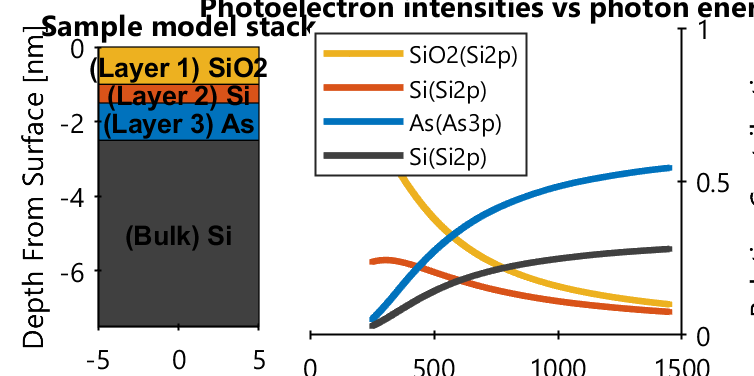

pes_hv          = linspace(250, 1450, 1e3);                     % Defining the incident photon energy
lyr_mat         = {'SiO2', 'Si', 'As', 'Si'};                   % Defining the material of each layer, from left to right (top-to-bottom on the schematic).
lyr_cls         = {'Si2p', 'Si2p', 'As3p', 'Si2p'};     % Defining the core-level being probed for each layer.
lyr_thick       = {1.0, 0.5, 1.0, Inf};                         % Defining the thickness of each layer.
pes_model_4L    = nlayer_pes_model(lyr_mat, lyr_cls, lyr_thick, pes_hv);

## (3) A 5-layer model (a complicated structure just to demonstrate the maximum number of layers that can be used)

**(1) Defining the sample model stack and extracting photoelectron intensity contributions**

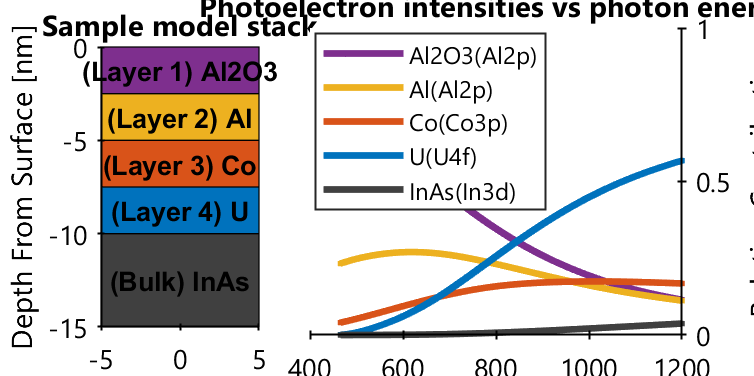

pes_hv          = linspace(100, 1200, 1e3);                                 % Defining the incident photon energy
lyr_mat         = {'Al2O3', 'Al', 'Co', 'U', 'InAs'};                       % Defining the material of each layer, from left to right (top-to-bottom on the schematic).
lyr_cls         = {'Al2p', 'Al2p', 'Co3p', 'U4f', 'In3d'};        % Defining the core-level being probed for each layer.
lyr_thick       = {2.5, 2.5, 2.5, 2.5, Inf};                                % Defining the thickness of each layer.
pes_model_5L    = nlayer_pes_model(lyr_mat, lyr_cls, lyr_thick, pes_hv);

**(2) Using a function to view the results of the PES Layer Stack if required**

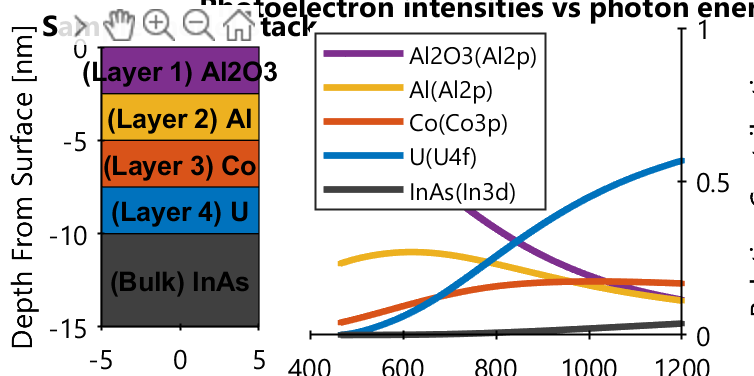

view_nlayer_pes_model(pes_model_5L);

# **Useful miscellaneous functions**

## **(1) Plotting a generic N-layered sample stack**

help view_nlayer_sample;

  fig = view_nlayer_sample(lyr_mat, lyr_thick, lyr_cols)
    This function plots the solutions to the 'nlayer_pes_model()' function;
    the n-layered sample stack and the corresponding photoelectron
    contribution from each one of the layers. The user can input the colors
    for each one of the layers using the 'lyr_cols' argument; this is
    convenient when you want to color-match the schematic to your own
    drawings.
 
    IN:
    -   lyr_mat:        Mx1 cell-vector of the material for each layer in the stack; e.g. "Si", "SiO2", "Al2O3"...
    -   lyr_thick:      Mx1 cell-vector of the thickness of each layer in the stack (in nano-metres)
    -   lyr_cols:       Mx1 cell-vector of the [R,G,B] color of each independent layer.
 
    OUT:
    -   fig:            MATLAB figure object with the ARPES data plotted.



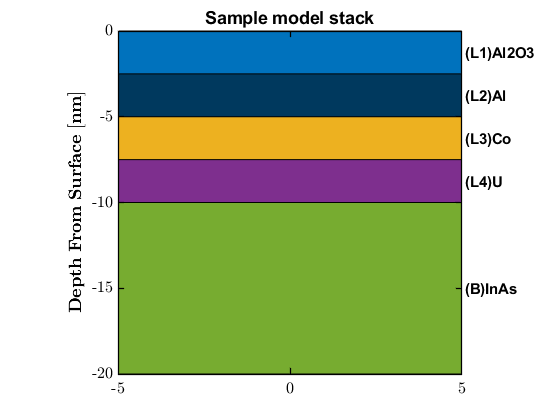

pp = plot_props();
lyr_mat         = {'Al2O3', 'Al', 'Co', 'U', 'InAs'};
lyr_thick       = {2.5, 2.5, 2.5, 2.5, Inf};
lyr_cols        = {pp.col.fit{2}, 0.5*pp.col.fit{2}, pp.col.fit{4}, pp.col.fit{5}, pp.col.fit{6}};
fig             = view_nlayer_sample(lyr_mat, lyr_thick, lyr_cols);